# 3. Creating Networks 

전이학습이 시간이 더 빠르다.

네트워크 만들기

load satData.mat % load the image and class labels
%사전훈련된 네트워크가 X, 이미지(XTrain, XTest), 클래스(YTrain, YTest)

### Peek into the data

Note the dimensions of the data.(데이터의 차원)

categories(YTrain) % View the class labels

ans = 6×1 cell 배열
    {'barren land'}
    {'building'   }
    {'grassland'  }
    {'road'       }
    {'trees'      }
    {'water'      }


size(XTrain) % View the dimensions of the training set of image data. 3000은 세번째로 두지 않음. 채널이랑 변하지 X

ans =           28          28           4        3000


View the infrared channel of the 507th land cover image in grayscale

507번째 토지 피복 이미지의 적외선 채널을 회색조로 봅니다.

(507번째 land cover image -> gracyscale)

a = [1 2 3 4 5 4 3 2]

a =      1     2     3     4     5     4     3     2


b = categorical(a) % 카테고리 형태로 변환

b = 1×8 categorical 배열
     1      2      3      4      5      4      3      2 


% categories(a) a는 더블형태여서 몇개의 카테고리가 있는지 알수 X 에러가 뜸.
categories(b) % 카테고리 형태로 변환했기 때문에 카테고리가 있는지 알수 O.

ans = 5×1 cell 배열
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}


summary(b) % 각 요소 몇개가 존재?

     1      2      3      4      5 
     1      2      2      2      1 


image507 = XTrain(:,:,4,507)

image507 = 28×28 uint8 행렬
    91   106   134   160   176   181   185   185   179   175   160   127   101    97    99   103   110   126   156   184   188   186   187   187   185   184   181   179
    89    86   103   136   159   163   172   182   187   189   171   123    87    87    90    92    92    99   121   157   179   187   187   187   186   183   180   177
    95    85    87   100   115   126   154   177   183   187   178   152   112    89    83    85    87    91    99   125   161   180   186   189   187   183   181   179
    97    95    86    87   101   131   158   169   178   183   181   177   165   128    94    87    89    91    92    99   125   161   182   188   186   183   183   180
    92    98    96    85    85   107   134   151   166   171   174   180   182   167   131   100    91    87    83    84    94   121   159   182   185   184   184   182
    90    90    95    93    82    88   107   141   155   149   146   171   180   180   175   139    93    79    67    56    62   

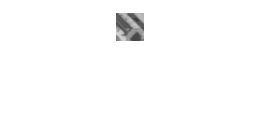

imshow(image507)

disp(image507)

  1 ~ 16번 열

    91   106   134   160   176   181   185   185   179   175   160   127   101    97    99   103
    89    86   103   136   159   163   172   182   187   189   171   123    87    87    90    92
    95    85    87   100   115   126   154   177   183   187   178   152   112    89    83    85
    97    95    86    87   101   131   158   169   178   183   181   177   165   128    94    87
    92    98    96    85    85   107   134   151   166   171   174   180   182   167   131   100
    90    90    95    93    82    88   107   141   155   149   146   171   180   180   175   139
    99    89    89    95    94    85    86   108   131   137   133   170   183   190   197   184
   108    99    88    86    92    93    85    85   102   126   149   173   186   190   196   198
   101   106    99    88    87    94    92    82    86   108   137   162   172   181   188   188
    86    99   108    99    87    85    90    91    83    87   103   136   157   169   177   183
    84    85    9

label507 = YTrain(507)

label507 = categorical
     building 


% imshow()

layers = imageInputLayer([28,28,4]); %4채널임
%레이어를 만들어야함.

convolution2dLayer([3,3],20);


a = [1 2 3 4 5]

a =      1     2     3     4     5


b = [1;2;3;4;5]

b =      1
     2
     3
     4
     5



b = a'

b =      1
     2
     3
     4
     5


b = transpose(a)

b =      1
     2
     3
     4
     5


## Create a Network from Layers

레이어에서 네트워크 생성

### Create the CNN Layers

Create a column vector of 7 layers named `layers`, with the layers in the order shown below.

`imageInputLayer``(``inputSize``)`

`convolution2dLayer``(``filterSize``,``numFilters``)`

`reluLayer``()`

`maxPooling2dLayer``(``poolSize``)`

`fullyConnectedLayer``(``numClasses``)`

`softmaxLayer``()`

`classificationLayer``()`

Use the following information to choose the inputs for the layers:

- Each image is size 28-by-28-by-4.

- The convolution layer should have a 20 filters of size 3-by-3.

- The pooling layer should have a pool size of 3-by-3.

- There are six classes.

layers = [imageInputLayer([28,28,4]); convolution2dLayer([3,3], 20);...
    reluLayer(); maxPooling2dLayer([3,3]); fullyConnectedLayer(6); softmaxLayer(); classificationLayer()]

layers =   다음 계층을 포함한 7×1 Layer 배열:

     1   ''   영상 입력          28×28×4 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      20개 3×3 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     3   ''   ReLU             ReLU
     4   ''   2차원 최댓값 풀링   3×3 최댓값 풀링 (스트라이드: [1  1], 채우기: [0  0  0  0])
     5   ''   완전 연결          6 완전 연결 계층
     6   ''   소프트맥스         소프트맥스
     7   ''   분류 출력          crossentropyex

View the network architecture

analyzeNetwork(layers)

### Training Options

Create training options named `options`. Use the algorithm `"sgdm"`, set the maximum number of epochs to `5`, and set the initial learning rate to `0.0001`.

options = trainingOptions("sgdm", "MaxEpochs",5,"InitialLearnRate",0.0001);
% ,"Plots","training-progress"

### Train the Network

landnet = trainNetwork(XTrain, YTrain, layers, options)

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：００　｜　　　　　　２０．３１％　｜　　　　３５．２１４７　｜　１．００００ｅ－０４　｜
｜　　　　　　　３　｜　　　　　　５０　｜　　　　　００：００：０２　｜　　　　　　８０．４７％　｜　　　　１３．２５５５　｜　１．００００ｅ－０４　｜
｜　　　　　　　５　｜　　　　　１００　｜　　　　　００：００：０４　｜　　　　　　９５．３１％　｜　　　　　０．６６７６　｜　１．００００ｅ－０４　｜
｜　　　　　　　５　｜　　　　　１１５　｜　　　　　００：００：０４　｜　　　　　　９３．７５％　｜　　　　　２．２０９８　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 최대 Epoch가 완료되었습니다.


landnet =   SeriesNetwork - 속성 있음:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


### Classify and Evaluate the Network

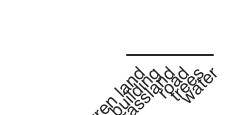

testPrediction = classify(landnet, XTest);  % Prediction by the network
confusionchart(YTest,testPrediction) % Visualization in a confusion matrix

## Convolutional Layer, Performing Convolutions

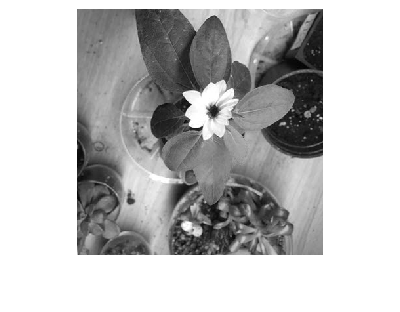

im = imread("sunflower.jpg"); % Load a sample image
redIm = im(:,:,1); % Extract the red channel(RGB)
imshow(redIm)

1. Create a 3-by-3 filter(often called 'kernel') that blurs an image and use the filter with the `conv2` function.

이미지를 흐리게 하는 3X3 필터(커널)를 만들고 CNN2 함수와 함께 사용합니다.

blurkernel = 1/9*ones(3) %3X3 단위행렬에 1/9을 곱함. 이미지를 흐리게 하기 위함.

ans =      1     1
     1     1


blurkernel =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


% 3X3 = 9. 필터를 사용할 때 픽셀의 평균을 계산하기 위함.
blurConv = conv2(blurkernel, redIm) 

blurConv =    12.8889   26.3333   40.2222   41.4444   42.0000   41.8889   41.5556   41.4444   40.8889   40.2222   39.3333   39.0000   38.7778   38.7778   39.1111   39.5556   39.6667   39.7778   40.0000   40.5556   40.7778   40.4444   39.7778   39.1111   38.0000   37.3333   37.1111   37.8889   38.5556   38.7778   38.5556   38.0000   37.2222   36.5556   36.0000   35.7778   35.6667   35.7778   36.0000   36.3333   36.7778   37.7778   39.0000   39.5556   39.1111   38.3333   38.0000   37.7778   37.5556   37.1111
   25.7778   52.5556   80.3333   82.6667   83.7778   83.4444   82.7778   82.5556   81.4444   80.2222   78.5556   78.1111   77.7778   77.8889   78.3333   79.0000   79.2222   79.5556   79.8889   80.6667   81.1111   80.7778   79.5556   77.8889   75.2222   73.6667   73.2222   74.7778   76.1111   76.6667   76.3333   75.4444   74.2222   73.2222   72.3333   71.7778   71.4444   71.5556   72.0000   72.5556   73.4444   75.3333   77.7778   78.7778   77.8889   76.4444   75.8889   75.5556   75.00

%conv2 = 2차원 컨볼루션(합성곱) 연산 수행 함수.

View the result using `imshow` function. Note that it is often useful to use a second argument to imshow when displaying grayscale images. Using empty brackets as the second input will scale the display based on the minimum and maximum values present in the image.

imshow 함수를 사용하여 결과를 확인합니다. 회색조 이미지를 표시할 때 imshow의 두 번째 인수를 사용하는 것이 유용한 경우가 많습니다. 빈 괄호를 두 번째 입력으로 사용하면 이미지에 있는 최소값과 최대값을 기준으로 디스플레이 크기가 조정됩니다. 

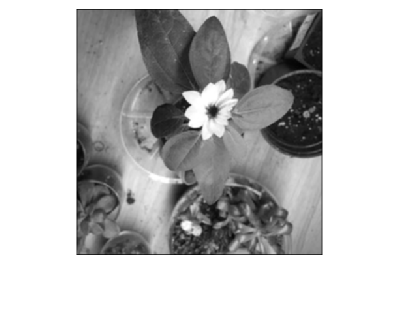

imshow(rescale(blurConv)) % == imshow(blurConv,[])

2. Create a 3-by-3 filter that detects edges and use the filter.

Sobel 엣지 필터는 영상 처리 및 컴퓨터 비전에서 주로 엣지 감지(Edge Detection)에 사용되는 필터 중 하나입니다. 엣지 감지는 영상에서 물체의 윤곽선(엣지)을 찾아내는 작업으로, 객체와 배경 간의 경계를 식별하는 데 도움이 됩니다. Sobel 필터는 이러한 엣지 검출을 수행하는데 사용됩니다.

Sobel 엣지 필터는 두 개의 3x3 커널 또는 마스크(가로 방향 및 세로 방향)를 사용하여 영상의 각 픽셀에 대한 그래디언트(gradient)를 계산합니다. 이 그래디언트는 해당 픽셀에서 엣지의 강도와 방향을 나타냅니다.

- 수평 방향(Sobel X): 이 커널은 엣지가 수평으로 놓인 경우에 감지됩니다. 수평 방향으로 변화가 큰 부분은 양수 값으로 감지되며, 엣지 아닌 부분은 0 또는 음수 값으로 나타납니다.

- 수직 방향(Sobel Y): 이 커널은 엣지가 수직으로 놓인 경우를 감지합니다. 수직 방향으로 변화가 큰 부분은 양수 값으로 감지되며, 엣지 아닌 부분은 0 또는 음수 값으로 나타납니다.

% 인터넷에 edge filter 검색해보기, sobel edge filter
edgeKernel = [0,1,0;1,-4,1;0,1,0];
edgeConv = conv2(edgeKernel, redIm)

edgeConv =      0   116   121   125   127   126   124   124   125   119   118   117   116   116   117   119   120   118   120   122   123   122   119   117   116   109   111   114   116   117   116   114   112   109   108   107   107   107   108   109   110   112   118   121   117   114   114   114   112   112
   116  -227  -123  -127  -131  -128  -123  -124  -133  -115  -118  -117  -114  -114  -115  -121  -124  -113  -120  -125  -127  -124  -117  -117  -125  -103  -113  -118  -120  -122  -119  -116  -114  -106  -107  -105  -107  -106  -108  -109  -110  -108  -122  -129  -117  -112  -114  -116  -110  -115
   116  -112     2    -5    -2    -2     1     0    -8     7    -1     2     0     1    -2     1    -2     1    -3     0     0    -3    -2     2    -3    10     2     0     0     0    -2     2     0     0     0     0     2     1    -1    -2     3     2    -1    -8     0     4    -1    -3     0     1
   116  -111     0    -3    -3     0     3     2    -4     4     0     0     0    -1  

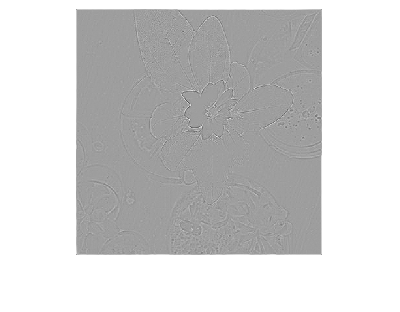

imshow(edgeConv, [])

## Viewing Learned Filters

Load and display an image with different colored flowers.

im = imread("roses.JPG")

im = 270×500×3 uint8 배열
im(:,:,1) =

   139   139   139   139   139   139   139   139   137   138   138   139   140   141   141   141   140   140   140   140   141   141   141   141   141   141   142   142   143   143   144   144   144   144   145   145   146   147   147   147   146   146   146   147   147   148   148   148   148   148   148   148   149   149   149   149   151   151   152   153   155   156   157   157   159   160   160   161   162   163   164   164   164   164   164   164   164   164   164   164   164   164   164   163   163   163   163   163   158   158   158   157   157   157   156   156   156   156   156   156   156   156   156   156   156   156   157   157   157   158   158   158   160   161   161   161   161   162   162   162   160   160   160   159   159   159   158   158   156   156   156   156   156   156   156   156   157   157   157   158   158   158   159   159   157   157   158   159   160   160   161   161   160   161   161   162   163   163   164   164   

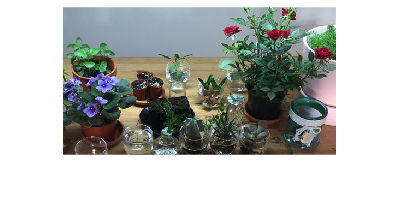

imshow(im)

Load GoogLeNet and saves the layers in a variable

구글넷을 로드하고 레이어를 변수에 저장

net = googlenet % 구글넷 로드 % 에드온 -> 설치

net =   DAGNetwork - 속성 있음:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = net.Layers % 레이어 변수에 저장

layers =   다음 계층을 포함한 144×1 Layer 배열:

     1   'data'                           영상 입력              224×224×3 영상 (정규화: 'zerocenter')
     2   'conv1-7x7_s2'                   2차원 컨벌루션          64개 7×7×3 컨벌루션(스트라이드: [2  2], 채우기: [3  3  3  3])
     3   'conv1-relu_7x7'                 ReLU                  ReLU
     4   'pool1-3x3_s2'                   2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  1  0  1])
     5   'pool1-norm1'                    교차 채널 정규화        교차 채널 정규화 (요소당 채널 5개)
     6   'conv2-3x3_reduce'               2차원 컨벌루션          64개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     7   'conv2-relu_3x3_reduce'          ReLU                  ReLU
     8   'conv2-3x3'                      2차원 컨벌루션          192개 3×3×64 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     9   'conv2-relu_3x3'                 ReLU                  ReLU
    10   'conv2-norm2'                    교차 채널 정규화        교차 채널 정규

l =   Convolution2DLayer - 속성 있음:

              Name: 'conv1-7x7_s2'

   하이퍼파라미터
        FilterSize: [7 7]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [3 3 3 3]
      PaddingValue: 0

   학습 가능한 파라미터
           Weights: [7×7×3×64 single]
              Bias: [1×1×64 single]

  모든 속성 표시


analyzeNetwork(net)

The `Weights` property of a layer contains that layer's weights. Weights are learned during training. Since GoogLeNet is a pretrained network, it has already learned weights that will find useful features. In this activity, you will inspect these weights in more detail.

Save the weights of the second layer to a variable and view the array of weights

레이어의 Weights 속성에는 해당 레이어의 가중치가 포함됩니다. 훈련 중에 가중치가 학습됩니다. GoogLeNet은 사전 훈련된 네트워크이므로 유용한 기능을 찾을 수 있는 가중치를 이미 학습했습니다. 이 활동에서는 이러한 가중치를 더 자세히 검사합니다.

두 번째 레이어의 가중치를 변수에 저장하고 가중치 배열 보기

Stride: [2,2] 2칸씩 이동해서 필터링 >> 빈공간(가장자리가 날아갈수도 O)이 생기니까 Padding(위, 아래, 왼쪽, 오른쪽 순서)을 설정.

layers(2)

ans =   Convolution2DLayer - 속성 있음:

              Name: 'conv1-7x7_s2'

   하이퍼파라미터
        FilterSize: [7 7]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [3 3 3 3]
      PaddingValue: 0

   학습 가능한 파라미터
           Weights: [7×7×3×64 single]
              Bias: [1×1×64 single]

  모든 속성 표시


weightLayer2 = layers(2).Weights

weightLayer2 = 7×7×3×64 single 배열
weightLayer2(:,:,1,1) =

    0.2290    0.1553   -0.0366   -0.2719   -0.2654   -0.1182   -0.0461
    0.0798   -0.0726   -0.2621   -0.4031   -0.3669   -0.0964    0.0031
   -0.0413   -0.1354   -0.2717   -0.4117   -0.1016    0.2899    0.2039
   -0.0976   -0.1944   -0.3115   -0.1588    0.4638    0.4693    0.0925
   -0.0791   -0.1483   -0.0779    0.2429    0.4363    0.1472   -0.0853
   -0.0377   -0.0296    0.0476    0.1915    0.1772   -0.0638   -0.1631
   -0.0261   -0.0119    0.0705    0.1137    0.0325   -0.1288   -0.1103


weightLayer2(:,:,2,1) =

   -0.2536   -0.1480   -0.0368    0.0830    0.1555    0.1493    0.0695
   -0.1202   -0.0393    0.1203    0.2832    0.2575    0.1918    0.0806
   -0.0390    0.1019    0.2608    0.2753    0.2314    0.2532    0.0917
    0.0741    0.1887    0.1857    0.2352    0.3369    0.1195   -0.0961
    0.1060    0.1308    0.1429    0.2124    0.0077   -0.1950   -0.1899
    0.0730    0.0977    0.0636   -0.0056   -0.1647   -0.1989  

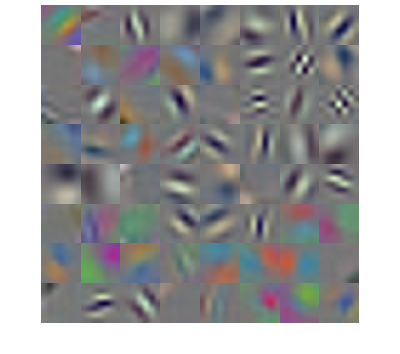

montage(rescale(weightLayer2))

You can view a specific filter by indexing into the weights. Extract the eleventh filter from the array of weights, then display it.

가중치를 색인화하여 특정 필터를 볼 수 있습니다. 가중치 배열에서 11번째 필터를 추출한 후 표시합니다.

filter11 = weightLayer2(:,:,:,11) % 3번째는 무조건 채널임!!

filter11 = 7×7×3 single 배열
filter11(:,:,1) =

   -0.0895   -0.0768   -0.0711    0.0394    0.1457    0.1333    0.0374
   -0.0858   -0.0485    0.0319    0.1247    0.2044    0.1512    0.1153
    0.0131    0.0410    0.1294    0.2090    0.2309    0.2007    0.0372
    0.0693    0.1165    0.1452    0.2312    0.2651    0.1012   -0.0704
    0.1196    0.1071    0.1481    0.1838    0.1287   -0.1380   -0.0765
    0.0737    0.1045    0.0933    0.0561   -0.0618   -0.1546   -0.0579
    0.1044    0.0729    0.0251   -0.0337   -0.0919   -0.1056   -0.0967


filter11(:,:,2) =

    0.1227    0.0489   -0.0739   -0.1725   -0.1990   -0.2691   -0.2370
   -0.0060   -0.0696   -0.1463   -0.2959   -0.3655   -0.4032   -0.2355
   -0.0192   -0.1180   -0.1866   -0.3524   -0.3817   -0.3189   -0.2582
   -0.0891   -0.1745   -0.2783   -0.3255   -0.2351   -0.2622   -0.1885
   -0.1270   -0.2314   -0.2528   -0.2432   -0.1733   -0.2647    0.0268
   -0.1566   -0.1564   -0.1539   -0.1306   -0.0973   -0.0127    0.2421
   -0.0558

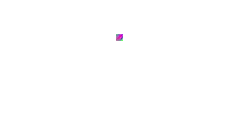

imshow(rescale(filter11))

The eleventh filter seems to be looking for the color pink. The image roses.jpg contains a few plants, but only the roses are red. Hence, only the roses should be positively activated from the eleventh filter.

열한 번째 필터는 핑크색을 찾는 것 같습니다. 이미지 rose.jpg에는 몇 개의 식물이 포함되어 있지만 장미만 빨간색입니다. 따라서 11번째 필터에서는 장미만이 적극적으로 활성화되어야 한다.

Let's see the eleventh filter actually activate the pink color from the image. (activation = 하나의 레이어에서 다음 레이어로 가는 것)

11번째 필터가 실제로 이미지의 분홍색을 활성화하는지 살펴보겠습니다.

actvn = activations(net, im, "conv1-7x7_s2")

actvn = 135×250×64 single 배열
actvn(:,:,1) =

  -53.8256  -57.5231  -46.9801  -46.5887  -47.1383  -47.1518  -46.9113  -47.0148  -47.1495  -47.0886  -46.9430  -46.1620  -47.8571  -48.1548  -48.2517  -49.0847  -47.7494  -47.2577  -47.1794  -46.4846  -49.8862  -49.1249  -49.1444  -49.1436  -48.9965  -49.2129  -48.9412  -49.5116  -49.1346  -49.6344  -49.4246  -50.0693  -49.1328  -49.8253  -49.7220  -47.6806  -50.8589  -51.4999  -51.4213  -51.5742  -51.0423  -51.7523  -51.1042  -54.2080  -52.4636  -50.4219  -49.3906  -50.1130  -49.8767  -49.9323  -49.9314  -49.7659  -50.0004  -50.0403  -49.9741  -50.4788  -49.8430  -50.1980  -49.9969  -49.7007  -49.7118  -50.2487  -49.6034  -49.6963  -50.0554  -49.7207  -49.9314  -50.1145  -49.8376  -49.9097  -50.0224  -49.6100  -50.4530  -49.6078  -50.2314  -50.0752  -50.2051  -49.9450  -50.3434  -52.0017  -52.6062  -45.9784  -46.2453  -49.3061  -53.1032  -51.2073  -50.0555  -50.6981  -50.1989  -50.4091  -50.3029  -49.9316  -50.6944  -49.9669  -50.5410  -49

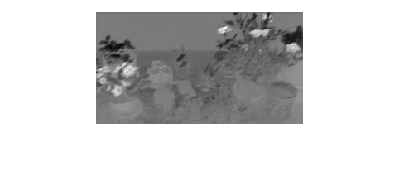

imshow(rescale(actvn(:,:,11)))